% Sample random combinations of 3-segment arms, and see how their
% workspaces compare.

% Sample arm designs with varying outer radii
rho_range = [0.02, 0.08];
N_segs = 6;
N_arms = 30;
mat_rhos = rand(N_segs, N_arms) * (rho_range(2) - rho_range(1)) + mean(rho_range)/2;

% Hold the inner radii constant at 0.01
rho_inner = 0.01 * ones(N_segs, 1);

l_0 = 0.5;

arms = ArmSeries.empty(N_arms, 0);
for i = 1 : size(mat_rhos, 2)
    rho_outer_i = mat_rhos(:, i);
    arms(i) = ArmSeriesFactory.varying_taper_2d_antagonist_arm(rho_inner, rho_outer_i, l_0);
    arms(i).set_mechanics(GinaMuscleMechanics(l_0), [2, 3]);
    arms(i).set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
end

arms(N_arms + 1) = ArmSeriesFactory.varying_taper_2d_antagonist_arm(rho_inner, [0.08, 0.075, 0.07, 0.03, 0.02, 0.01], l_0);

% For each arm, find the tip pose for a set pressure and load
p = [100; 0; 60; 0];
Q = [0; -10; 0];

endpoints = zeros(3, length(arms));
f = waitbar(0);
for i = 1 : length(arms)
    arm_i = arms(i);
    arm_i.solve_equilibrium_gina(p, Q);
    endpoints(:, i) = Pose2.vee(arm_i.get_tip_pose);
    
    waitbar(i / length(arms), f, sprintf("Arm %i", i));
end

fzero residual is nonzero (> 0.01). Printing: 
    0.0001    0.0004   -0.0030   -0.0114   -0.0003   -0.0066
   -0.0000   -0.0000    0.0000    0.0001    0.0000   -0.0000
   -0.0250   -0.0509    0.2507    0.8183   -0.0322    0.6846
fzero residual is nonzero (> 0.01). Printing: 
    0.0016   -0.0022   -0.0043   -0.0010   -0.0041   -0.0291
   -0.0001   -0.0000    0.0000    0.0000    0.0001    0.0001
   -0.4908    0.2347    0.4407    0.1317    0.4383    2.1809
fzero residual is nonzero (> 0.01). Printing: 
    0.0003   -0.0201   -0.0222   -0.0365   -0.0202   -0.0371
   -0.0000   -0.0000    0.0000    0.0001    0.0000   -0.0001
   -0.1013    0.0100    0.3149    1.2046    0.2098    1.6592
fzero residual is nonzero (> 0.01). Printing: 
    0.0003    0.0003   -0.0009   -0.0190   -0.0003   -0.0045
   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0000
   -0.0449   -0.0440    0.0946    1.2513   -0.0288    0.4727
fzero residual is nonzero (> 0.01). Printing: 
   -0.0006   -0.0006   -0.0018   

close(f)

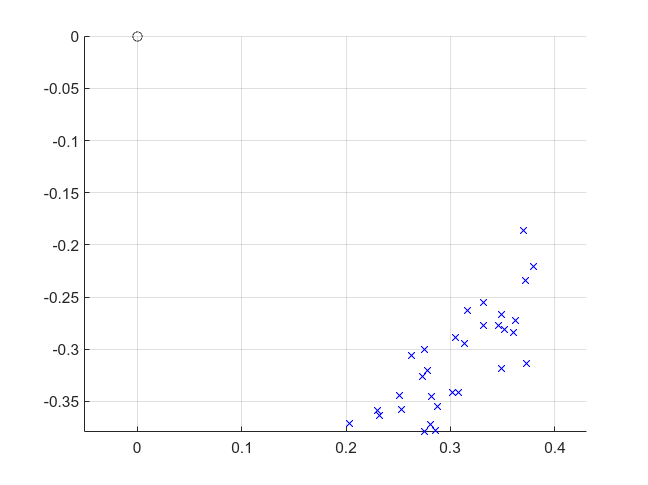

figure()
hold on
plot(endpoints(1, :), endpoints(2, :), 'bx')
plot(0, 0, 'ko')
grid on
axis equal

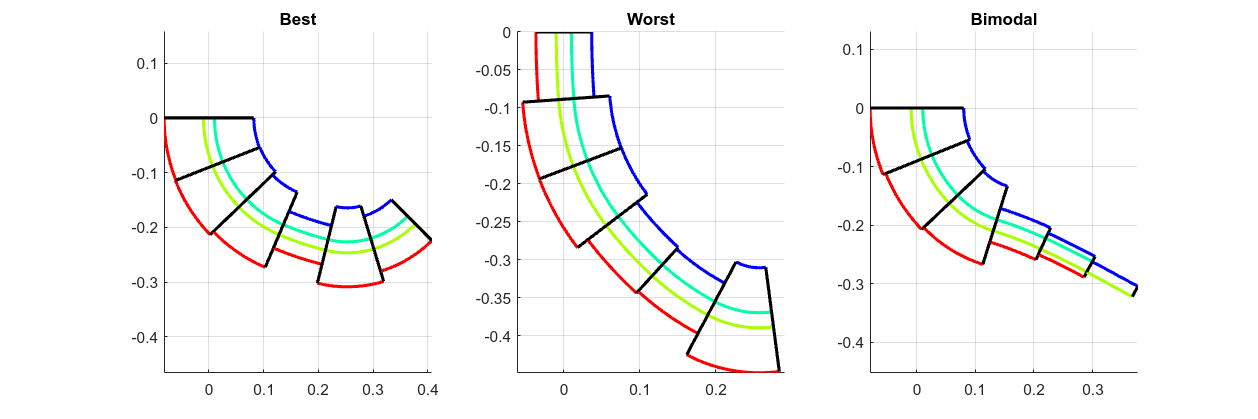

[~, i_best] = max(endpoints(2, :));
[~, i_worst] = min(endpoints(2, :));

fig = figure("Position", [0, 0, 1500, 500]);
ax = subplot(1, 3, 1);
Plotter2D.plot_arm_series(arms(i_best), ax);
title("Best")

ax = subplot(1, 3, 2);
Plotter2D.plot_arm_series(arms(i_worst), ax);
title("Worst")

ax = subplot(1, 3, 3);
Plotter2D.plot_arm_series(arms(end), ax);
title("Bimodal")

% For each arm, sample M points from its workspace
N_pressures= 20;
p_range = [0, 100];
pressures = rand(arms(1).N_rods, N_pressures) * (p_range(2) - p_range(1)) / 2 + mean(p_range);

Q = [0; -10; 0];

cell_endpoints = cell(N_pressures, N_arms);

f = waitbar(0);
count = 0;
for i_arm = 1 : length(arms)
    arm_i = arms(i_arm);
    for i_pressure = 1 : N_pressures
        p_i = pressures(:, i_pressure);
        arm_i.solve_equilibrium_gina(p_i, Q);
        cell_endpoints{i_pressure, i_arm} = Pose2.vee(arm_i.get_tip_pose());

        count = count + 1;
        waitbar(count / (N_pressures * N_arms), f, sprintf("Arm %i, Pressure %i", i_arm, i_pressure));
    end
end

close(f);

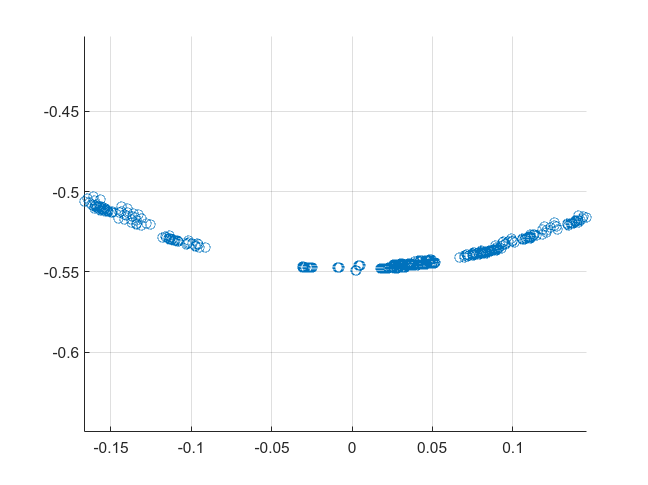

end_poses = [cell_endpoints{:}];
figure()
scatter(end_poses(1, :), end_poses(2, :));
axis equal
grid on

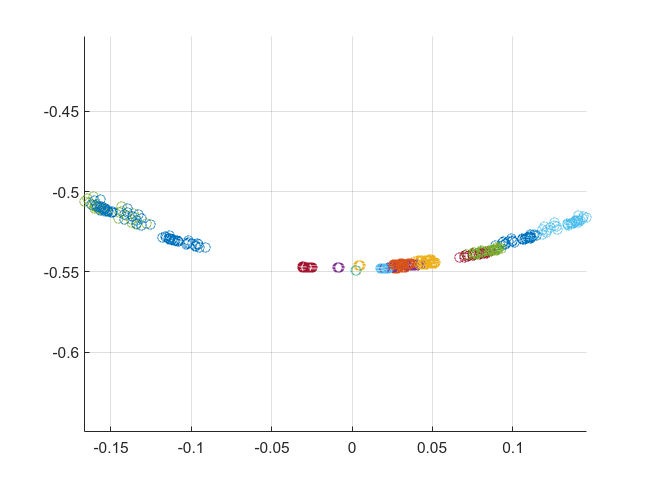

figure()
hold on
for i = 1 : size(cell_endpoints, 1)
    endpoints_p_i = [cell_endpoints{i, :}];
    
    scatter(endpoints_p_i(1, :), endpoints_p_i(2, :));
end
axis equal
grid on